# Script de los Ejercicios sobre clasificacion y evaluacion

## Situate en el directorio donde se encuentra corpus

## limpiamos el entorno de matlab

clear
close

## cargamos los datos desde corpus.mat

load corpus.mat

## preparamos un conjunto de entrenamiento de 2 clases

## XT2clases: variables predictivas del corpus de entrenamiento con 2 clases

## YT2clases: etiequeta de salida del corpus de entrenamiento

XT1=Xpitraining(Ytraining==1,:);
XT2=Xpitraining(Ytraining==2,:);
YT1=Ytraining(Ytraining==1);
YT2=-1*ones(size(Ytraining(Ytraining==2)));
XT2clases=[XT1;XT2];
YT2clases=[YT1;YT2];

## preparamos un conjunto de test de 2 clases

## Xt2clases: variables predictivas del corpus de test con 2 clases

## Yt2clases: etiequeta de salida del corpus de test

Xt1=Xpitest(Ytest==1,:);
Xt2=Xpitest(Ytest==2,:);
Yt1=Ytest(Ytest==1);
Yt2=-1*ones(size(Ytest(Ytest==2)));
Xt2clases=[Xt1;Xt2];
Yt2clases=[Yt1;Yt2];

## ejercicio 1: clasificador gausiano

## clasificacion binaria LDA y QDA

XT=XT2clases;
YT=YT2clases;
Xt=Xt2clases;
Yt=Yt2clases;

## estimacion y clasificacion lineal de las clases 1 y 2

[class,errT,POSTERIOR,logp,coeff] = classify(Xt, XT, YT);

## estudia la variable POSTERIOR

POSTERIOR

POSTERIOR =     0.2948    0.7052
    0.0164    0.9836
    0.2121    0.7879
    0.0025    0.9975
    0.0129    0.9871
    0.1611    0.8389
    0.0234    0.9766
    0.0030    0.9970
    0.1618    0.8382
    0.0029    0.9971


## estudia la variable coeff para averiguar la frontera de decision

coeff

coeff = 2×2 struct array with fields:
    type
    name1
    name2
    const
    linear


## calcula el error de test

errT

errT = 0.1043

## estimacion y clasificacion cuadratica de las clases 1 y 2

[class,errT,POSTERIOR,logp,coeff] = classify(Xt, XT, YT, "quadratic");
errT

errT = 0.0764

## estimacion y clasificacion lineal de las clases 1, 2 y 3

[class,errT,POSTERIOR,logp,coeff] = classify(Xpitest, Xpitraining, Ytraining, "quadratic");

## estimacion del error de test

errT

errT = 0.0827

## calculo de la matriz de confusion

confus(Ytest,class)

ans =     43     6     3
     6    16     1
     1     2    13


## Clasificacion de 3 clases basada en la extraccion de caracteristicas

## mediante PCA

## tipificar la union de conjuntos de entrenamiento y test

[XTtip, m, s] = tipificar([Xpitraining]);
    
l = size(Xpitest,1)

l = 91

Xttip = (Xpitest - repmat(m,[l,1])) ./ repmat(s,[l,1])

Xttip =    -1.0861   -0.9644   -0.3476   -0.4702   -0.2401   -0.5951   -0.5913   -0.4873   -1.6090   -1.1759   -1.0422   -0.2125    1.2500    1.3362    1.4700
   -0.8464   -0.5855   -0.8189   -0.7733   -0.6026   -1.2626   -1.4009   -0.8755    0.3150   -0.0648   -0.0060    3.0855    0.9469    0.8453    0.4115
    0.9246    0.1900   -0.4976   -0.4923   -0.0011   -0.5230   -0.7334   -0.2198    0.7546   -0.7249   -0.6402    1.9195    0.1148    0.0881    0.0245
   -1.3798   -1.4850   -1.1238   -1.2078   -1.2687   -1.4609   -1.4785   -1.3174   -1.0148   -1.0627   -1.2701    1.3884    1.8380    1.7034    0.1299
   -1.0043   -1.6996   -1.1871   -1.4570   -1.1213   -1.3270   -1.4680   -1.5534   -1.1631   -1.5428   -1.5572   -0.6401    1.6716    1.7923    0.6336
   -0.7085   -1.1218   -0.8563   -0.9268   -1.8608   -1.3748   -1.0803   -1.1490   -2.7352   -0.4553   -0.6831   -0.8042   -0.3461   -0.2612    1.9484
   -0.3229   -1.1703   -0.8780   -0.9901   -1.0640   -1.2951   -1.0515   -0.6118   -0.

## estudiamos kolmogorov-smirnov, miramos k-s de 1 var en mitad de la sesion

[h,p,k,c] = kstest(XTtip(:,floor(size(XTtip,2)/2)),[],0.05,0);

## Proyeccion PCA del conjunto de entrenamiento tipificado

[coeff,score,latent,tsquared,explained,mu] = pca(XTtip);

## Proyeccion del conjunto de test tipificado mediante loadings (biplot)

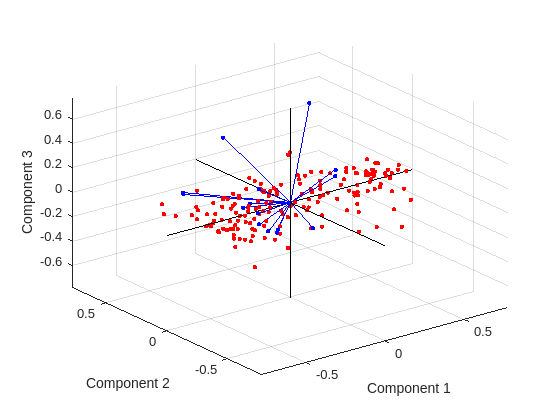

biplot(coeff(:,1:3), 'Scores', score(:,1:3))

## clasificacion de 3 clases con los 10 primeros scores

[class,err,POSTERIOR,logp,coeff] = classify(Xpitest,XTtip, Ytraining)

class =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


err = 0.1006

POSTERIOR =     0.9968    0.0032    0.0000
    0.9983    0.0017    0.0000
    0.9797    0.0203    0.0000
    0.9999    0.0001    0.0000
    0.9998    0.0002    0.0000
    0.9745    0.0255    0.0000
    0.9980    0.0020    0.0000
    0.9652    0.0300    0.0048
    0.9667    0.0333    0.0000
    0.9996    0.0004    0.0000


logp =   -57.7217
  -38.0902
  -26.7631
  -59.5980
  -66.4811
  -17.5749
  -36.8223
  -19.7590
  -29.2559
  -38.7694


coeff = 3×3 struct array with fields:
    type
    name1
    name2
    const
    linear


## ejercicio 2:Knn

## Clasifica el conjunto de test de las clases 1, 2 y 3 con un k=1

model = fitcknn(Xpitraining, Ytraining,'NumNeighbors',1)

model =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2 3]
           ScoreTransform: 'none'
          NumObservations: 209
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


class = predict(model, Xpitest)

class =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


calcular error

loss(model, Xpitest, Ytest)

ans = 0.2287

## Calculo de la matriz de confusion

confus(Ytest,class)

ans =     45     3     4
     8    14     1
     1     4    11


## Repite el proceso anterior para k desde 1 a 90.

for t=1:90
    model = fitcknn(Xpitraining, Ytraining,'NumNeighbors',t);
    class = predict(model, Xpitest);
    M=confus(Ytest,class);
    loss(model, Xpitest, Ytest)
    ACC(t)=sum(diag(M))/length(class);
end

ans = 0.2287

ans = 0.2503

ans = 0.2621

ans = 0.2619

ans = 0.2296

ans = 0.2513

ans = 0.2403

ans = 0.2394

ans = 0.2076

ans = 0.2181

ans = 0.2080

ans = 0.1974

ans = 0.2081

ans = 0.1970

ans = 0.2081

ans = 0.2408

ans = 0.2191

ans = 0.2191

ans = 0.2191

ans = 0.2302

ans = 0.2302

ans = 0.2191

ans = 0.2302

ans = 0.2414

ans = 0.2524

ans = 0.2302

ans = 0.2302

ans = 0.2302

ans = 0.2409

ans = 0.2413

ans = 0.2302

ans = 0.2297

ans = 0.2302

ans = 0.2302

ans = 0.2524

ans = 0.2631

ans = 0.2524

ans = 0.2524

ans = 0.2635

ans = 0.2746

ans = 0.2636

ans = 0.2746

ans = 0.2746

ans = 0.2746

ans = 0.2524

ans = 0.2636

ans = 0.2636

ans = 0.2636

ans = 0.2746

ans = 0.2746

ans = 0.2746

ans = 0.2636

ans = 0.2636

ans = 0.2636

ans = 0.2746

ans = 0.2746

ans = 0.2746

ans = 0.2746

ans = 0.2529

ans = 0.2640

ans = 0.2640

ans = 0.2529

ans = 0.2529

ans = 0.2529

ans = 0.2529

ans = 0.2529

ans = 0.2529

ans = 0.2529

ans = 0.2529

ans = 0.2529

ans = 0.2640

ans = 0.2529

ans = 0.2640

ans = 0.2640

ans = 0.2751

ans = 0.2640

ans = 0.2751

ans = 0.2751

ans = 0.2640

ans = 0.2640

ans = 0.2861

ans = 0.2750

ans = 0.2861

ans = 0.2750

ans = 0.2861

ans = 0.2971

ans = 0.2860

ans = 0.2860

ans = 0.2754

ans = 0.2975

## Muestra los resultados obtenidos en un grafico

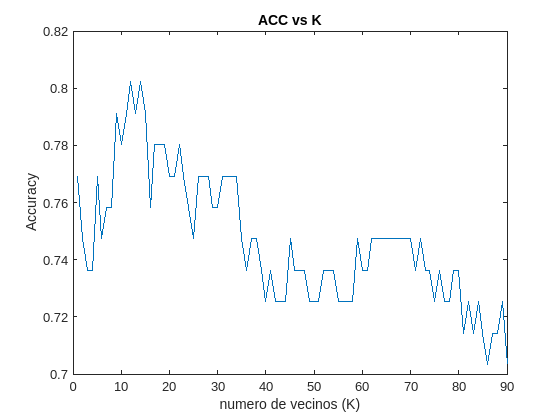

plot(1:90,ACC);
title('ACC vs K');
xlabel('numero de vecinos (K)');
ylabel('Accuracy');